% Cowan-style neural network with Linear Rectified Transfer function 
SampleTime = 100; % unit s 
dt = 0.01; % unit s 

t = 0:dt:SampleTime;
% linear rectified function
transfer_func_linear = @(x) max(0, x);
transfer_func_quadratic = @(x) max(0, x)^2;



- The bistable case

% Set the connection weight matrix
% Choose c = 0.2 
c = 0.2; 
W = [1 -0.5;

     -0.5 1]; 
sim_num = 500;
b = 0;
[r,g,p,s] = sim_network(W, c, b, transfer_func_linear, SampleTime, dt,sim_num); 
% Plot two runs of the random process
% figure 
% subplot(1,2,1)
% hold on 
% plot(t,r(1,:,1))
% plot(t,r(2,:,1))
% hold off
% subplot(1,2,2)
% plot(t,r(1,:,2))
% hold on 
% plot(t,r(2,:,2))
% xlabel("Second")
% ylabel("Firing Rate")
% hold off
X = squeeze(r(1,2:end,:))';
Y = squeeze(r(2,2:end,:))';
te_result_ytox = transfer_entropy_main(X,Y,5,5);
te_result_xtoy = transfer_entropy_main(Y,X,5,5);
% Plot the transfer entropy at each time step
% figure
% plot(t(7:end),te_result_ytox)
% hold on 
% plot(t(7:end),te_result_xtoy)
mean(te_result_xtoy), mean(te_result_ytox)

ans = 0.0055

ans = 0.0056

2. Asymmetric drive

c = 0; 
W = [0 2;
     0 0]; 
sim_num = 100;
b = 0;
[r,g,p,s] = sim_network(W, c, b, transfer_func_linear, SampleTime, dt,sim_num); 
% Plot two runs of the process
% figure
% subplot(1,2,1)
% hold on 
% plot(t,r(1,:,1))
% plot(t,r(2,:,1))
% hold off
% subplot(1,2,2)
% hold on
% plot(t,r(1,:,2))
% plot(t,r(2,:,2))
% xlabel("Second")
% ylabel("Firing Rate")
% hold off
X = squeeze(r(1,2:end,:))';
Y = squeeze(r(2,2:end,:))';
te_result_ytox = transfer_entropy_main(X,Y,2,2);
te_result_xtoy = transfer_entropy_main(Y,X,2,2);
% figure
% plot(t(4:end),te_result_ytox)
% hold on 
% plot(t(4:end),te_result_xtoy)
% hold off
mean(te_result_xtoy), mean(te_result_ytox)

ans = 0.0104

ans = 0.0131

Range the connection from y to x from 0 to 5. Expect to see TE from y to x increase and x to y stays the same. 

c = 0; 
p = 0:0.5:5;
te_result_ytox = zeros(0, length(p));
te_result_xtoy = zeros(0, length(p));
for i = 1:length(p)
    W = [0 p(i);
        0 0];
    sim_num = 100;
    b = 0;
    [r,~,~,~] = sim_network(W, c, b, transfer_func_linear, SampleTime, dt,sim_num);
    X = squeeze(r(1,2:end,:))';
    Y = squeeze(r(2,2:end,:))';
    te_result_ytox(i) = mean(transfer_entropy_main(X,Y,2,2));
    te_result_xtoy(i) = mean(transfer_entropy_main(Y,X,2,2));
end 

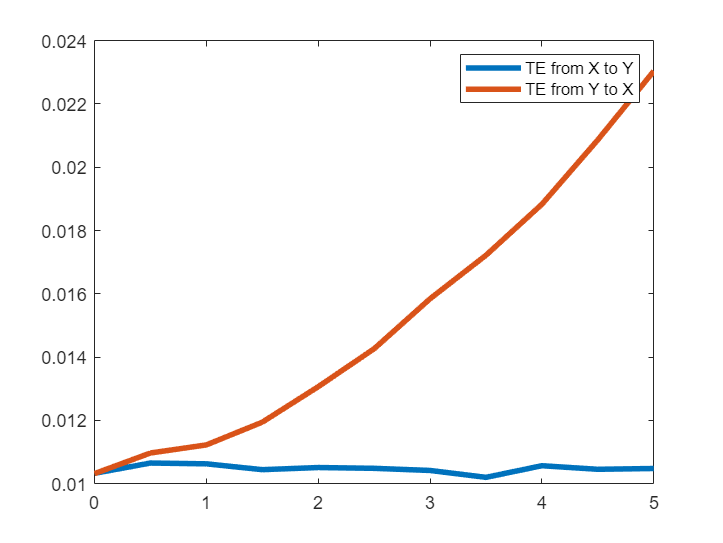

figure 
plot(p, te_result_xtoy, LineWidth=3)
hold on 
plot(p, te_result_ytox, LineWidth=3)
legend("TE from X to Y", "TE from Y to X")